%%Further Analysis%%

%Plotting mean r values of all cells (saved in r_values, need to be worked
%on) as histogram and gaussian fit on it
clear all 
close all

t=readtable('CA1int.xlsx');

t_srt=sortrows(t,42); % sort for mid gamma mean vector length
vLength_srt=t_srt{:,42};
k1=strfind(t_srt{:,11}, 'NGF');
a1=~cellfun(@isempty,k1(:));
k2=strfind(t_srt{:,11}, 'idNGF');
a2=~cellfun(@isempty,k2(:));


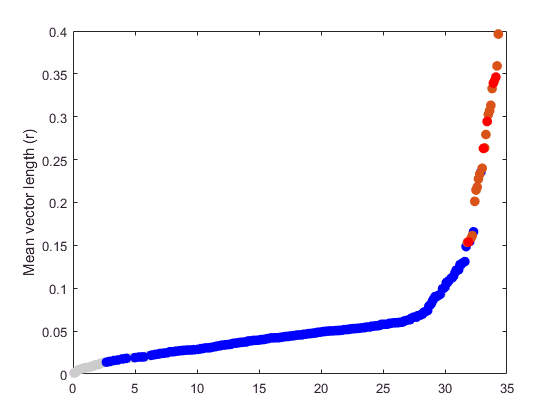

figure;
for je=1:size(vLength_srt,1)
    if t_srt{je,44}>=0.05 %pvalue of mid gamma coupling (significance)
          plot(0.1*je, vLength_srt(je), '.', 'Color', [0.8 0.8 0.8], 'MarkerSize', 25)
          hold on;
    end
end
for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && a1(je)==0
          plot(0.1*je, vLength_srt(je), '.', 'Color', 'b', 'MarkerSize', 25)
          hold on;
    end
end
for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && a1(je)==1 && a2(je)==0 %put. NGF
          plot(0.1*je, vLength_srt(je), '.', 'Color', [0.8500 0.3250 0.0980], 'MarkerSize', 25)
          hold on;
    end
end
for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && a1(je)==1 && a2(je)==1
          plot(0.1*je, vLength_srt(je), '.', 'Color', 'r', 'MarkerSize', 25)
          hold on;
    end
end


          
ylabel('Mean vector length (r)')

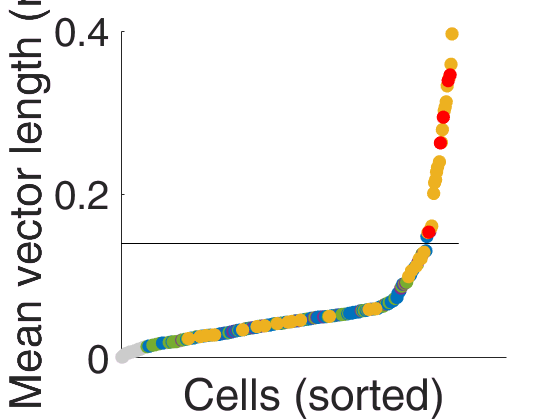

% sorted for mid gamma
figure;
notsig=0;
sigOri=0;
sigPyr=0;
sigRad=0;
sigLM=0;
for je=1:size(vLength_srt,1)
    if t_srt{je,44}>=0.05 && t_srt{je,41}>200
          scatter(0.1*je, vLength_srt(je), 100, [0.8 0.8 0.8], 'filled')
          hold on;
          notsig=notsig+1;
    end
end
for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && t_srt{je,7}==1 && t_srt{je,41}>200 %cells in st. oriens
          scatter(0.1*je, vLength_srt(je), 100, [0.4660 0.6740 0.1880], 'filled')
          hold on;
          sigOri=sigOri+1;
    elseif t_srt{je,44}<0.05 && t_srt{je,7}==2 && t_srt{je,41}>200 %cells in st.pyr
          scatter(0.1*je, vLength_srt(je), 100, [0 0.4470 0.7410], 'filled')
          hold on;
          sigPyr=sigPyr+1;
    elseif t_srt{je,44}<0.05 && t_srt{je,7}==3 && t_srt{je,41}>200 %cells in st.rad
          scatter(0.1*je, vLength_srt(je), 100, [0.4940 0.1840 0.5560], 'filled')
          hold on;
          sigRad=sigRad+1;
    end
end

for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && a2(je)==0 && t_srt{je,7}==4 && t_srt{je,41}>200 %cells in st.lm
        scatter(0.1*je, vLength_srt(je), 100, [0.9290 0.6940 0.1250], 'filled')
        hold on;
        sigLM=sigLM+1;
    end
end

for je=1:size(vLength_srt,1)
    if t_srt{je,44}<0.05 && a2(je)==1 && t_srt{je,41}>200 %identified NGF
        scatter(0.1*je, vLength_srt(je), 100, 'r', 'filled')
        hold on;
    end
end
line(xlim, [0.14, 0.14], 'Color', 'k')
ylabel('Mean vector length (r)')
xlabel('Cells (sorted)')
set(gca,'FontSize', 30,...
    'XTick', [],...
    'xticklabel', [])
box off

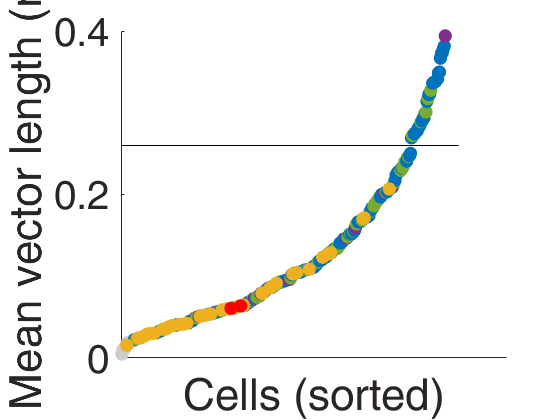

% sorted for fast gamma
t_srt=sortrows(t,53); % sort for fast gamma mean vector length
vLength_srt=t_srt{:,56};
k1=strfind(t_srt{:,11}, 'NGF');
a1=~cellfun(@isempty,k1(:));
k2=strfind(t_srt{:,11}, 'idNGF');
a2=~cellfun(@isempty,k2(:));
figure;
for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,55})>=0.05 && t_srt{je,52}>200
          scatter(0.1*je, abs(vLength_srt(je)), 100, [0.8 0.8 0.8], 'filled')
          hold on;
    end
end
for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,55})<0.05 && t_srt{je,7}==1 && t_srt{je,52}>200 %cells in st. oriens
          scatter(0.1*je, vLength_srt(je), 100, [0.4660 0.6740 0.1880], 'filled')
          hold on;
    elseif str2double(t_srt{je,55})<0.05 && t_srt{je,7}==2 && t_srt{je,52}>200 %cells in st.pyr
          scatter(0.1*je, vLength_srt(je), 100, [0 0.4470 0.7410], 'filled')
          hold on;
    elseif str2double(t_srt{je,55})<0.05 && t_srt{je,7}==3 && t_srt{je,52}>200 %cells in st.rad
          scatter(0.1*je, vLength_srt(je), 100, [0.4940 0.1840 0.5560], 'filled')
          hold on;
    end
end

for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,55})<0.05 && a2(je)==0 && t_srt{je,7}==4 && t_srt{je,52}>200 %cells in st.lm
        scatter(0.1*je, vLength_srt(je), 100, [0.9290 0.6940 0.1250], 'filled')
        hold on;
    end
end

for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,55})<0.05 && a2(je)==1 && t_srt{je,52}>200 %identified NGF
        scatter(0.1*je, vLength_srt(je), 100, 'r', 'filled')
        hold on;
    end
end
line(xlim, [0.26, 0.26], 'Color', 'k')
ylabel('Mean vector length (r)')
xlabel('Cells (sorted)')
set(gca,'FontSize', 30,...
    'XTick', [],...
    'xticklabel', [])
box off

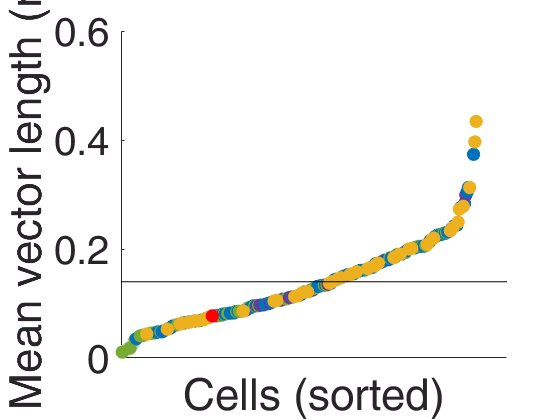

% sorted for slow gamma
t_srt=sortrows(t,64); % sort for slow gamma mean vector length
vLength_srt=t_srt{:,67};
k1=strfind(t_srt{:,11}, 'NGF');
a1=~cellfun(@isempty,k1(:));
k2=strfind(t_srt{:,11}, 'idNGF');
a2=~cellfun(@isempty,k2(:));
figure;
for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,66})>=0.05 && t_srt{je,63}>200
          scatter(0.1*je, abs(vLength_srt(je)), 100, [0.8 0.8 0.8], 'filled')
          hold on;
    end
end
for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,66})<0.05 && t_srt{je,7}==1 && t_srt{je,63}>200 %cells in st. oriens
          scatter(0.1*je, vLength_srt(je), 100, [0.4660 0.6740 0.1880], 'filled')
          hold on;
    elseif str2double(t_srt{je,66})<0.05 && t_srt{je,7}==2 && t_srt{je,63}>200 %cells in st.pyr
          scatter(0.1*je, vLength_srt(je), 100, [0 0.4470 0.7410], 'filled')
          hold on;
    elseif str2double(t_srt{je,66})<0.05 && t_srt{je,7}==3 && t_srt{je,63}>200 %cells in st.rad
          scatter(0.1*je, vLength_srt(je), 100, [0.4940 0.1840 0.5560], 'filled')
          hold on;
    end
end

for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,66})<0.05 && a2(je)==0 && t_srt{je,7}==4 && t_srt{je,63}>200 %cells in st.lm
        scatter(0.1*je, vLength_srt(je), 100, [0.9290 0.6940 0.1250], 'filled')
        hold on;
    end
end

for je=1:size(vLength_srt,1)
    if str2double(t_srt{je,66})<0.05 && a2(je)==1 && t_srt{je,63}>200 %identified NGF
        scatter(0.1*je, vLength_srt(je), 100, 'r', 'filled')
        hold on;
    end
end
line(xlim, [0.25, 0.25], 'Color', 'k')
ylabel('Mean vector length (r)')
xlabel('Cells (sorted)')
set(gca,'FontSize', 30,...
    'XTick', [],...
    'xticklabel', [])
box off

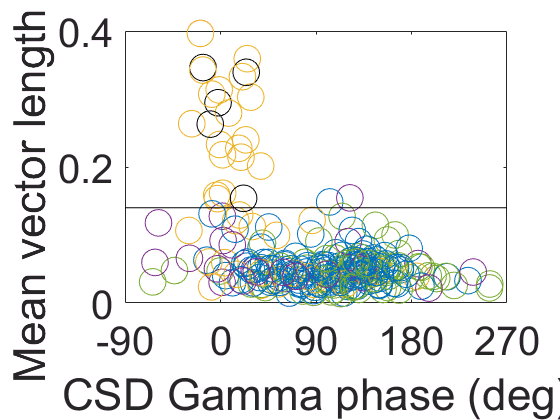

%Mean vector angle and length of all significant interneurons for mid-gamma

figure;

vLength=t{:,45};
vAngle=t{:,46};
k2=strfind(t{:,11}, 'idNGF');
idNGFid=~cellfun(@isempty,k2(:));
for je=1:size(vLength,1)
    if t{je,44}<0.05 && t{je,7}==1 && t{je,41}>200 %cells in st.ori
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.4660 0.6740 0.1880], 'MarkerSize', 20)
        hold on;
    end
    if t{je,44}<0.05 && t{je,7}==2 && t{je,41}>200 %cells in st.pyr
        plot(vAngle(je), vLength(je), 'o', 'Color', [0 0.4470 0.7410], 'MarkerSize', 20)
        hold on;
    end
    if t{je,44}<0.05 && t{je,7}==3 && t{je,41}>200 %cells in st.rad
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.4940 0.1840 0.5560], 'MarkerSize', 20)
        hold on;
    end
    if t{je,44}<0.05 && t{je,7}==4 && t{je,41}>200 %cells in st.lm
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.9290 0.6940 0.1250], 'MarkerSize', 20)
        hold on;
    end
    if t{je,44}<0.05 && t{je,7}==4 && t{je,41}>200  && idNGFid(je)==1 %identified neurogliaforms
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.0 0.0 0.0], 'MarkerSize', 20)
        hold on
    end
end


line(xlim, [0.14, 0.14], 'Color', 'k')

xlabel('CSD Gamma phase (deg)')
ylabel('Mean vector length (r)')
xlim([-90 270])
ylim([0 0.4]);
xticks(-90:90:270)
xticklabels(-90:90:270)
set(gca,'FontSize', 30)

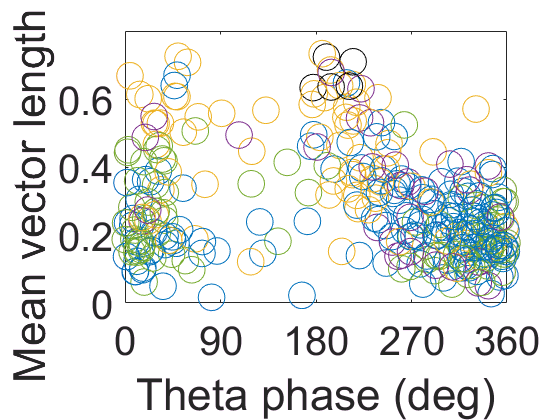

%Mean vector angle and length of all significant interneurons for theta

figure;

vLength=t{:,20};
vAngle=t{:,19};
k1=strfind(t{:,11}, 'NGF');
k2=strfind(t{:,11}, 'idNGF');
NGFid=~cellfun(@isempty,k1(:));
idNGFid=~cellfun(@isempty,k2(:));
for je=1:size(vLength,1)
    if str2double(t{je,21})<0.05 && t{je,7}==1 && t{je,17}>200 %cells in st.ori
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.4660 0.6740 0.1880], 'MarkerSize', 20)
        hold on;
    end
    if str2double(t{je,21})<0.05 && t{je,7}==2 && t{je,17}>200 %cells in st.pyr
        plot(vAngle(je), vLength(je), 'o', 'Color', [0 0.4470 0.7410], 'MarkerSize', 20)
        hold on;
    end
    if str2double(t{je,21})<0.05 && t{je,7}==3 && t{je,17}>200 %cells in st.rad
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.4940 0.1840 0.5560], 'MarkerSize', 20)
        hold on;
    end
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200 %cells in st.lm
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.9290 0.6940 0.1250], 'MarkerSize', 20)
        hold on;
    end
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200  && NGFid(je)==1 && idNGFid(je)==0 %identified neurogliaforms
        plot(vAngle(je), vLength(je), 'o', 'Color', 'r', 'MarkerSize', 20)
        hold on
    end
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200  && idNGFid(je)==1 %identified neurogliaforms
        plot(vAngle(je), vLength(je), 'o', 'Color', [0.0 0.0 0.0], 'MarkerSize', 20)
        hold on
    end
end

xlabel('Theta phase (deg)')
ylabel('Mean vector length (r)')
xlim([0 360])
ylim([0 0.8]);
xticks(0:90:360)
xticklabels(0:90:360)
set(gca,'FontSize', 30)

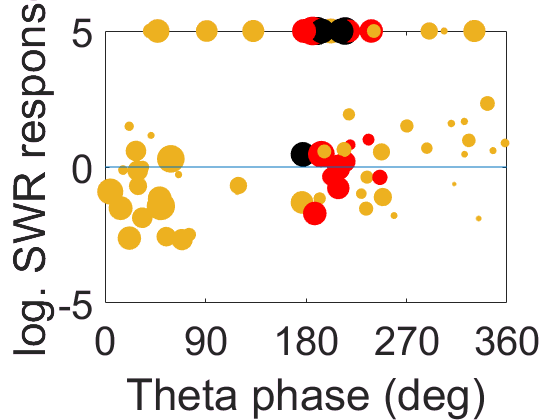

%Mean vector angle and length (theta) and swr response of all significant interneurons in lm

figure;

vLength=t{:,20};
vAngle=t{:,19};
SWR=t{:,35};
k1=strfind(t{:,11}, 'NGF');
k2=strfind(t{:,11}, 'idNGF');
NGFid=~cellfun(@isempty,k1(:));
idNGFid=~cellfun(@isempty,k2(:));
dotSize=[];
for je=1:size(vLength,1)
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200 %cells in st.lm
        plot(vAngle(je), log(SWR(je)), '.', 'Color', [0.9290 0.6940 0.1250], 'MarkerSize', vLength(je)*100)
        hold on;
        dotSize=[dotSize vLength(je)];
        if isnan(SWR(je))
            plot(vAngle(je), 5, '.', 'Color', [0.9290 0.6940 0.1250], 'MarkerSize', vLength(je)*100)
            hold on;
            dotSize=[dotSize vLength(je)];
        end
    end
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200  && NGFid(je)==1 && idNGFid(je)==0 %identified neurogliaforms
        plot(vAngle(je), log(SWR(je)), '.', 'Color', 'r', 'MarkerSize', vLength(je)*100)
        hold on
        dotSize=[dotSize vLength(je)];
        if isnan(SWR(je))
            plot(vAngle(je), 5, '.', 'Color', 'r', 'MarkerSize', vLength(je)*100)
            hold on;
            dotSize=[dotSize vLength(je)];
        end
    end
    if str2double(t{je,21})<0.05 && t{je,7}==4 && t{je,17}>200  && idNGFid(je)==1 %identified neurogliaforms
        plot(vAngle(je), log(SWR(je)), '.', 'Color', [0.0 0.0 0.0], 'MarkerSize', vLength(je)*100)
        hold on
        dotSize=[dotSize vLength(je)];
        if isnan(SWR(je))
            plot(vAngle(je), 5, '.', 'Color', [0.0 0.0 0.0], 'MarkerSize', vLength(je)*100)
            hold on;
            dotSize=[dotSize vLength(je)];
        end
    end
end
dotSize=sort(dotSize');
xlabel('Theta phase (deg)')
ylabel('log. SWR response')
xlim([0 360])
%ylim([0 11]);
xticks(0:90:360)
xticklabels(0:90:360)
set(gca,'FontSize', 30)
line(xlim, [0 0])

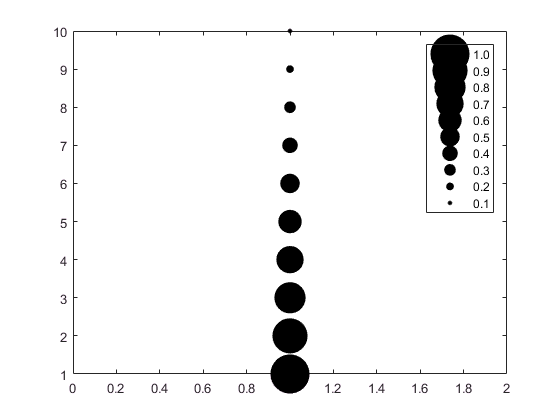

figure;
h=plot(1, 1:10, '.', 'Color', 'k', 'MarkerSize', 0.1*100);
for x=1:10
    set(h(11-x), 'MarkerSize', x*10)
end
legend('1.0', '0.9', '0.8', '0.7', '0.6', '0.5', '0.4', '0.3', '0.2', '0.1')

opts = statset('Display','final');
[id,C] = kmeans(vLength_srt,3,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 5 iterations, total sum of distances = 5.40014.
Replicate 2, 12 iterations, total sum of distances = 5.43587.
Replicate 3, 3 iterations, total sum of distances = 5.84208.
Replicate 4, 6 iterations, total sum of distances = 5.84208.
Replicate 5, 3 iterations, total sum of distances = 5.84208.
Best total sum of distances = 5.40014


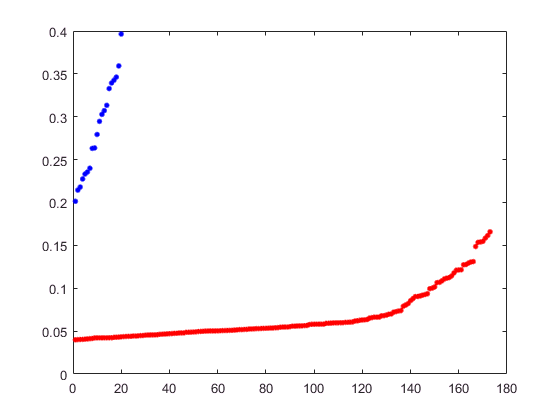

plot(vLength_srt(id==1),'r.','MarkerSize',12)
hold on
plot(vLength_srt(id==2),'b.','MarkerSize',12)

plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 

Index exceeds matrix dimensions.

legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

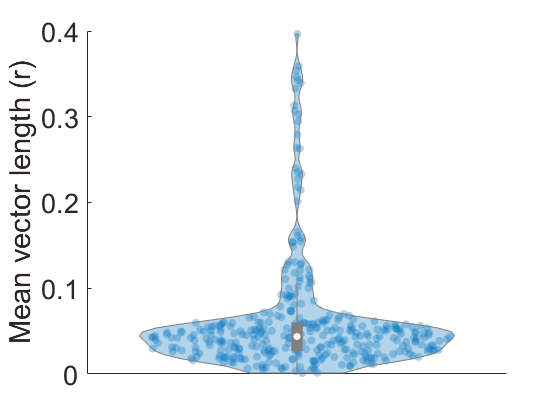

figure;
violinplot(vLength_srt);
ylabel('Mean vector length (r)')
set(gca, 'FontSize', 20,...
    'XTick', [],...
    'xticklabel', [])

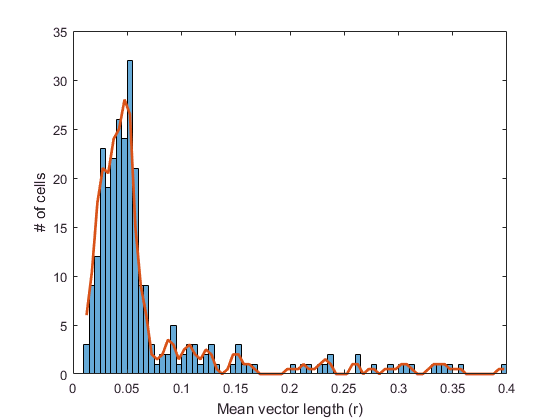

figure;
h=histogram(vLength_srt(t_srt{:,44}<0.05), 'BinWidth', 0.005);
hold on
Filtered_Data=Gaussian1D(h.Values,2);
firstBinCen=h.BinLimits(1)+h.BinWidth/2;
lastBinCen=h.BinLimits(2)-h.BinWidth/2;
x=linspace(firstBinCen, lastBinCen, h.NumBins);
plot(x, Filtered_Data,...
    'LineWidth', 2)
xlabel('Mean vector length (r)')
ylabel('# of cells')

%theta phase vs mid-gamma coupling strength
mid_vLength=t{:,45};
th_phase=str2double(t{:,19});
%plot([th_phase th_phase], [mid_vLength mid_vLength], '.')
figure;
for je=1:size(t,1)
    if t{je,7}~=4 && t{je,41}>200 && t{je,44}<0.05
       plot(th_phase(je), mid_vLength(je), 'b.', 'MarkerSize', 40)
       hold on
    end
end

Error using plot
Invalid second data argument


for je=1:size(t,1)
    if t{je,7}==4 && t{je,41}>200 && t{je,44}<0.05
       plot(th_phase(je), mid_vLength(je), '.', 'Color', [0.9290 0.6940 0.1250], 'MarkerSize', 40)
       hold on
    end
end
hold off
xlabel('Theta phase (deg)')
ylabel('Mean vector length (r) for mid-gamma')
set(gca, 'FontSize', 30)
xticks(0:90:360)
xticklabels(0:90:360)
xlim([0 360])



% Fast(coloumn 3:22) and slow(coloumn 24:43)-gamma coupling for all identified (red) and putative (blue) neurogliaform cells
figure;
for je=6:23
    NGF_fastput(je-5,:) = couple{je+24, 24:43}./max(couple{je+24, 24:43});
end
meanFastPut=nanmean(NGF_fastput);
line ([gmbins gmbins+360], [meanFastPut meanFastPut], 'LineWidth', 4, 'Color', [0 0.4470 0.7410]);
hold on
for je=1:18
    lh=plot([gmbins gmbins+360], repmat(NGF_fastput(je,:),1,2), 'linewidth', 4, 'Color', [0 0.4470 0.7410]);
    lh.Color=[0 0.4470 0.7410,0.2];
    hold on
end

for je=1:5
    NGF_fast(je,:) = couple{je+24, 24:43}./max(couple{je+24, 24:43});
end
meanFast=nanmean(NGF_fast);
line ([gmbins gmbins+360], [meanFast meanFast], 'LineWidth', 4, 'Color', [0.6350 0.0780 0.1840]);
hold on
for je=1:5
    lh=plot([gmbins gmbins+360], repmat(NGF_fast(je,:),1,2), 'linewidth', 4, 'Color', [0.6350 0.0780 0.1840]);
    lh.Color=[0.6350 0.0780 0.1840,0.2];
    hold on
end


%x=[0:1:720]; y=(cosd(x+180)+1).*0.5; 
% line (x,y, 'Color', 'k', 'LineWidth', 2) % theta
%y=[0:0.1:1];
%axis ([0 720 0 1]);
set (gca, 'Xtick', 0:90:720, ... 
    'FontSize',30)
xlabel ('Gamma phase (deg)'); ylabel ('Firing rate norm.')
%pozi=get(gca,'Position'); pozi=[pozi(1) pozi(2) 1.2*pozi(3) 1.2*pozi(4)]; set(gca,'Position',pozi)

xlim([0 720])
ylim([0 1.1])
set(gca, 'Clipping', 'off')